# ROS Robot Motion Control

## Modeling and Control of Robotic Manipulators

Reminder: Follow the steps in the instruction files in the moodle course for using VM, ROS and Matlab:

- [Instructions on VM and ROS](https://moodle.tu-dortmund.de/mod/resource/view.php?id=698961)

- [Instructions on UR ROS Package](https://moodle.tu-dortmund.de/mod/resource/view.php?id=698965)

- [Instructions on Matlab and ROS](https://moodle.tu-dortmund.de/mod/resource/view.php?id=698963)

**Recommended Matlab Version: 2020b**

## Inverse Kinematics

#### 1.	Inverse Kinematics

Generate an inverse kinematics solver object `iksolver` for the rigid body tree object *ur*.

%import robot ur10.urdf
ur10 = importrobot('ur10.urdf'); 

%Generate a inverse kinematics solver object for the rigid body tree ur
ikSolver = robotics.InverseKinematics('RigidBodyTree',ur10);

#### 2.	Define a target pose

Define a target pose in terms of a transform *tformTargetPose* that results from a translation $$[d_x \ d_y \ d_z]^T =[0.6 \ 0 \ 1.0]^T$$ and a rotation by Euler angles $$[\phi \ \theta \ \psi]^T=[\pi/4  \ \pi/4  \ -\pi/4]^T$$.	

targetPosition=[0.6 0 1.0];
targetOrientation=[pi/4, pi/4, -pi/4];

% %get tform of target pose
tformTrans=trvec2tform(targetPosition);
tformRot=eul2tform(targetOrientation);
tformTargetPose=tformTrans*tformRot;

#### 3.    Determine the targetConf with the initialized ikSolver object above

Determine the inverse kinematics solution *targetConf* with the method `ik` for the target pose of the end effector link frame *'ee_link'* with a unit error weight vector $$w=[1 \ 1 \ 1 \ 1 \ 1 \ 1]$$. 

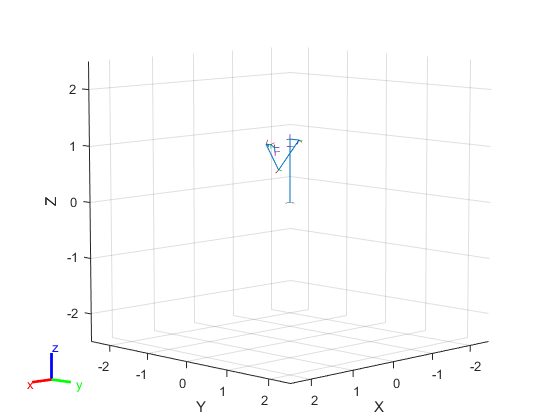

weights = ones(6,1);
initial_guess = JointVec2JointConf(ur10,[0 1 -2 2 1 1]);
%initialpose = ur10.homeConfiguration;
[targetConf, solnInfo] = ikSolver('ee_link',tformTargetPose,weights,initial_guess);
ur10.show(initial_guess);

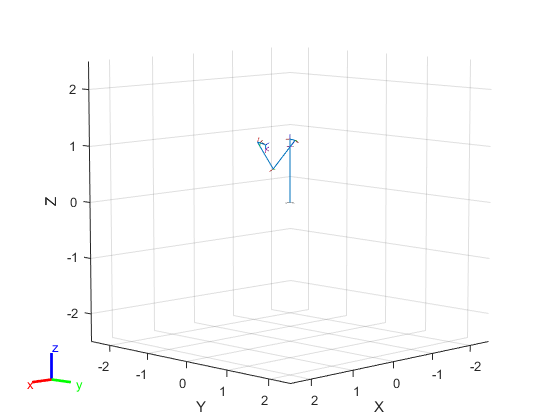

figure(2)
ur10.show(targetConf);

## ROS

#### 4.    Simulate the UR robot motion in Gazebo

To simulate the UR robot motion in Gazebo invoke the following launch files:

		`roslaunch ur_launch ur10_sim_gazebo.launch rqt:=false`

The launch file starts Gazebo (hidden), RViz and the ROS controllers without the RQT interface.	

#### 5.    Connect to ROS

Connect to the ROS master on the local host from within Matlab with `rosinit`

rosinit('http://ubuntu:11311/')

Initializing global node /matlab_global_node_85421 with NodeURI http://192.168.2.108:52191/


#### 6.    Show topics

Query the topics that are currently available on the network and obtain information about the topic *'/ur10/joint_states'* in particular the message type.

You notice that the *JointStatePublisher* publishes on the topic *'/ur10/joint_states'*

rostopic list

/clicked_point                                                                      
/clock                                                                              
/gazebo/link_states                                                                 
/gazebo/model_states                                                                
/gazebo/parameter_descriptions                                                      
/gazebo/parameter_updates                                                           
/gazebo/set_link_state                                                              
/gazebo/set_model_state                                                             
/initialpose                                                                        
/move_base_simple/goal                                                              
/robot_workspace_monitor/dynamic_obstacle_marker                                    
/robot_workspace_monitor/dynamic_obstacle_marker_array           

rostopic info /ur10/joint_states

Type: sensor_msgs/JointState
 
Publishers:
* /gazebo (http://ubuntu:40147/)
 
Subscribers:
* /robot_state_publisher (http://ubuntu:36411/)
* /ur_distance_publisher (http://ubuntu:39331/)


rostopic info ur10/vel_based_pos_traj_controller/command

Type: trajectory_msgs/JointTrajectory
 
Publishers:
 
Subscribers:
* /gazebo (http://ubuntu:40147/)


rosmsg show sensor_msgs/JointState

% This is a message that holds data to describe the state of a set of torque controlled joints. 
%
% The state of each joint (revolute or prismatic) is defined by:
%  * the Position of the joint (rad or m),
%  * the Velocity of the joint (rad/s or m/s) and 
%  * the Effort that is applied in the joint (Nm or N).
%
% Each joint is uniquely identified by its Name
% The Header specifies the Time at which the joint states were recorded. All the joint states
% in one message have to be recorded at the same Time.
%
% This message consists of a multiple arrays, one for each part of the joint state. 
% The goal is to make each of the fields optional. When e.g. your joints have no
% Effort associated with them, you can leave the Effort array empty. 
%
% All arrays in this message should have the same size, or be empty.
% This is the only way to uniquely associate the joint Name with the correct
% states.


std_msgs/Header Header

char[] Name
double[] Position
double[] Velocity
double[] Effort



rosmsg show trajectory_msgs/JointTrajectory

std_msgs/Header Header
char[] JointNames
JointTrajectoryPoint[] Points


#### 7.    Instantiate a subscriber for the topic above and receive messages

Instantiate a subscriber in Matlab for this topic and receive a message for the joint states.

Inspect the field *jointstate.Position* which denotes the vector of joint variables. The first six elements correspond to joints *shoulder_pan_joint*` to `*wrist_3_joint*`.`

jointStateSub = rossubscriber('/ur10/joint_states');
currentJointState = jointStateSub.receive();
currentJointState.Position

ans =      0
     0
     0
     0
     0
     0


## Trajectory Control via Topic Interface

#### 8.    Information about ros message and helper function

Trajectory commands of message type *trajectory_msgs/JointTrajectory* are published on the topic  */ur10/vel_based_pos_traj_controller/command. *Instantiate a message object and inspect the message type structure

`	jointCommandMsg=rosmessage('trajectory_msgs/JointTrajectory')	`

The message type has the components *Header*, *JointNames* and *Points*. *JointNames* refer to the joint names in the URDF description of the robot. *Points* is an array of waypoints (*JointTrajectoryPoint*) that constitutes the sequence of poses plus time intervals the robot is supposed to track. Each *JointTrajectoryPoint* of message type *trajectory_msgs/TrajectoryPoint* has the components *Positions*, *Velocities* and *Accelerations* which correspond to joint state vector $$\mathbf{q}$$, joint velocity vector $$\dot{\mathbf{q}}$$ and joint acceleration vector $$\ddot{\mathbf{q}}$$. The component *TimeFromStart* specifies the time stamp of the waypoint, relative to the message time defined in the header of the *trajectory_msgs/JointTrajectory* message.

The helper function 	

		`function [ jointTrajectoryMsg ] = JointVec2JointTrajectoryMsg(robot, q, t, qvel, qacc)`

maps the  $$n \times m$$ arrays of joint vectors *q*,  joint velocities *qvel* and joint accelerations *qacc* and the $$n \times 1$$ vector of time stamps onto the corresponding joint trajectory message. The input argument *qvel* and *qacc* are optional and assume default zero values if omitted. 

jointCommandMsg = rosmessage('trajectory_msgs/JointTrajectory')

jointCommandMsg =   ROS JointTrajectory message with properties:

    MessageType: 'trajectory_msgs/JointTrajectory'
         Header: [1×1 Header]
         Points: [0×1 JointTrajectoryPoint]
     JointNames: {0×1 cell}

  Use showdetails to show the contents of the message


jointCommandMsg.showdetails


  Header        
    Stamp      
      Sec  :  0
      Nsec :  0
    Seq     :  0
    FrameId :  
  Points        
  JointNames :  {}


#### 9.    Perform a point to point motion

Perform a point-to-point motion from the current configuration to the target configuration from task 3.	

%create publisher
jointTrajectoryPub = rospublisher('/ur10/vel_based_pos_traj_controller/command');

%convert target configuration
q_target = JointConf2JointVec(targetConf);
t_target = 2.5;

% time offset to let robot finish motion
t_offset = 3; % increase if robot does not reach it's configuration in time

%send target configuration to the robot 
jointTrajectoryPub.send(JointVec2JointTrajectoryMsg(ur10,q_target,t_target));
pause(t_target + t_offset)

#### 10.    Execute the rated loop that monitors the temporal evaluation of the joint state vector

The motion command is executed in a fire and forget manner. Replace the `pause` command with a rated loop that monitors the temporal evolution of the joint state vector by subscribing to the */ur10/joint_states* topic. 

The helper function

`	function [ jointState, jointVel ] = JointStateMsg2JointState( robot, jointMsg )	`

converts a joint state message into joint state and joint velocity vectors.

% Move to start configuration
q_home = [0 0 0 0 0 0]';
t_home = 2.5;
jointTrajectoryPub.send(JointVec2JointTrajectoryMsg(ur10,q_home',t_home));
pause(t_home+t_offset)

% Define joint velocity
%qvel=[1.0 1.0 1.0 1.0 1.0 1.0]';

% Create rate object
rate = 110; % Hz
rateObj=robotics.Rate(rate);
tf = t_target + 0.5;
rateObj.reset; % reset time of rate object

% Preallocation
N = tf*rate;
timeStamp=zeros(1,N);
jointStateStamped=zeros(6,N); % array to record joint pose
jointVelStamped=zeros(6,N); % array to record joint velocity

% Store start time
jointStateMsg=jointStateSub.receive();
t0=double(jointStateMsg.Header.Stamp.Sec)+ double(jointStateMsg.Header.Stamp.Nsec)*10^-9;

% Move and monitor
jointTrajectoryPub.send(JointVec2JointTrajectoryMsg(ur10,q_target,t_target));

for i=1:N
    % Receive and convert
     jointStateMsg=jointStateSub.receive();    
     [jointState, jointVel]=JointStateMsg2JointState(ur10,jointStateMsg);
    
    % Store signals
     jointStateStamped(:,i)=jointState';
     jointVelStamped(:,i)=jointVel';
     timeStamp(i)=double(jointStateMsg.Header.Stamp.Sec)+ double(jointStateMsg.Header.Stamp.Nsec)*10^-9-t0;
     
     waitfor(rateObj);
end

#### 11.    Plot the joint state and joint velocity

Plot the joint state and joint velocity vector versus time as shown in figure 6. The joint motion profile is quintic to guarantee continuity of joint state, velocities and accelerations at way-points.

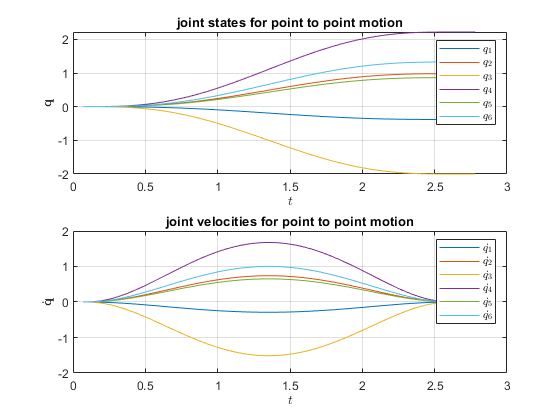

figure(1);
subplot(211);

plot(timeStamp,jointStateStamped);
xlabel('$t$','Interpreter','Latex');
ylabel('$\mathbf{q}$','Interpreter','Latex');
legend({'$q_1$','$q_2$','$q_3$','$q_4$','$q_5$','$q_6$'},'Interpreter','Latex');
title('joint states for point to point motion');
grid on

subplot(212);

plot(timeStamp,jointVelStamped);
xlabel('$t$','Interpreter','Latex');
ylabel('$\dot{\mathbf{q}}$','Interpreter','Latex');
legend({'$\dot{q_1}$','$\dot{q_2}$','$\dot{q_3}$','$\dot{q_4}$','$\dot{q_5}$','$\dot{q_6}$'},'Interpreter','Latex');
title('joint velocities for point to point motion');
grid on

#### 12.    Prepare a motion via two way-points

A general trajectory is composed of a sequence of way-points. The joint trajectory commands accept multiple joint configurations with time stamps to be traversed in that order. Command a trajectory  composed of the intermediate way-point $$\mathbf{q}_{target}$ and final way-point $$\mathbf{q}_2=[-1 \ 0 \ -1 \ 1 \ 0 \ 2]$$. 

% Back to home
jointTrajectoryPub.send(JointVec2JointTrajectoryMsg(ur10,q_home',t_home));
pause(t_home+t_offset)

% Create second waypoint
t_targets=[2.5 6.0];
qf = [-1 0 -1 1 0 2]';
q_targets=[q_target' qf];

%task='12';    
task='14';    

switch task
    case '12'
        % stop at intermediate way-point
         qvel=zeros(6,2); % stop at intermediate way-point
        
        
    case '14'   
         % stop at intermediate way-point
         qvel1 = [-0.4 0 0 -0.3 0 0]';
         qvelf = [0 0 0 0 0 0]';
         qvel=[qvel1 qvelf];
        
end

#### 13.	Perform motion via two way-points

Command, record and plot the joint motion through multiple way-points with the same code as for the point to point motion. Notice, that 

`	function [ jointTrajectoryMsg ] = JointVec2JointTrajectoryMsg(robot, q, t, qvel, qacc)`

accepts, a matrix of way-points *q* and a vector of time instances *t*. The motion is shown in figure 7. Notice, that the joint velocities at the intermediate way-point go to zero. This is desirable for joints $$q_2,q_5$$ which either stop or undergo a motion reversal at the first way-point. However, it seems awkward that joints $$q_1,q_4$$ come to a stop before continuing their movement.

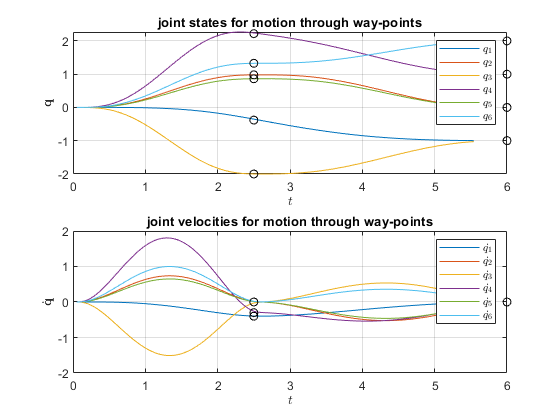

tf = t_targets(end) + 1.0;
rateObj.reset; % reset time of rate object

% Preallocation
N = tf*rate;
timeStamp=zeros(1,N);
jointStateStamped=zeros(6,N); % array to record joint pose
jointVelStamped=zeros(6,N); % array to record joint velocity

% % Store start time
jointStateMsg=jointStateSub.receive();
t0=double(jointStateMsg.Header.Stamp.Sec)+ double(jointStateMsg.Header.Stamp.Nsec)*10^-9;

% Move and monitor
 jointTrajectoryPub.send(JointVec2JointTrajectoryMsg(ur10,q_targets',t_targets,qvel'));

for i=1:N
%     % Receive and convert
     jointStateMsg=jointStateSub.receive();    
     [jointState, jointVel]=JointStateMsg2JointState(ur10,jointStateMsg);
    
%     % Store signals
     jointStateStamped(:,i)=jointState';
     jointVelStamped(:,i)=jointVel';
     timeStamp(i)=double(jointStateMsg.Header.Stamp.Sec)+ double(jointStateMsg.Header.Stamp.Nsec)*10^-9-t0;
     
     waitfor(rateObj);
end

figure(2);
subplot(211);

plot(timeStamp,jointStateStamped);

hold on;
 for i=1:size(q_targets,2)
     plot(t_targets(i),q_targets(:,i),'ko')
 end
hold off;

xlabel('$t$','Interpreter','Latex');
ylabel('$\mathbf{q}$','Interpreter','Latex');
legend({'$q_1$','$q_2$','$q_3$','$q_4$','$q_5$','$q_6$'},'Interpreter','Latex');
title('joint states for motion through way-points');
grid on

subplot(212);

plot(timeStamp,jointVelStamped);

hold on;
 for i=1:size(q_targets,2)
     plot(t_targets(i),qvel(:,i),'ko')
 end
hold off;

xlabel('$t$','Interpreter','Latex');
ylabel('$\dot{\mathbf{q}}$','Interpreter','Latex');
legend({'$\dot{q_1}$','$\dot{q_2}$','$\dot{q_3}$','$\dot{q_4}$','$\dot{q_5}$','$\dot{q_6}$'},'Interpreter','Latex');
title('joint velocities for motion through way-points');
grid on

#### 14.	Modify the joint trajectory from task 12 and perform task 12 and 13

Modify the joint trajectory command by imposing a velocity vector $$\dot{\mathbf{q}}_1=[-0.4 \ 0.0 \ 0.0 \ -0.3 \ 0.0 \ 0.0]$$ for the first way-point. Notice, that for a smooth motion the joint velocities $$\dot{q}_1,\dot{q}_4$$ should assume their maximum at the first way-point. The maximum velocity equals is twice as large as the average velocity given by 


$$\mathbf{q}_{avg}=\frac{\mathbf{q}_f-\mathbf{q}_i}{t_f}$$


in which $$q_f$$ denotes the final joint state, $$q_i$$ the initial joint state and $$t_f$$ the total time of motion. The commanded velocity at the final way-point $$\dot{\mathbf{q}}_2$$ should still be zero for all joints as the motion is supposed to stop at the end of the trajectory. The motion with corrected way-point velocities is shown in figure 6.

## Trajectory Control via Action Server and Client

#### 15.    Display the current list of actions on the ROS network

Display the current list of actions on the ROS network. Confirm that there is an action *'/ur10/vel_based_pos_traj_controller/follow_joint_trajectory' *and inspect the topic.

Notice, that goal message is of type *control_msgs/FollowJointTrajectoryGoal.*

rosaction list;

/ur10/vel_based_pos_traj_controller/follow_joint_trajectory


rosaction info '/ur10/vel_based_pos_traj_controller/follow_joint_trajectory';

Action Type: control_msgs/FollowJointTrajectory

Goal Message Type: control_msgs/FollowJointTrajectoryGoal
Feedback Message Type: control_msgs/FollowJointTrajectoryFeedback
Result Message Type: control_msgs/FollowJointTrajectoryResult

Action Server:
* /gazebo (http://ubuntu:40147/)

Action Clients: None



%rostopic list |grep '/ur10/vel_based_pos_traj_controller/follow_joint_trajectory'

#### 16.	Instantiate an action client and an empty goal message

Instantiate an action client *followJointTrajectoryActClient*  for the action *'/ur10/vel_based_pos_traj_controller/follow_joint_trajectory'*.

followJointTrajectoryTopicName=['/ur10/vel_based_pos_traj_controller/follow_joint_trajectory'];
[followJointTrajectoryActClient]=rosactionclient(followJointTrajectoryTopicName);
waitForServer(followJointTrajectoryActClient);

#### 17.    Inspect the structure of the goal message

Inspect the structure of *followJointTrajectoryMsg*. The field *followJointTrajectoryMsg.Trajectory* corresponds to	the message type that you previously used for the topic interface. The message contains additional specification for path, goal and time tolerance, to monitor the accuracy of the commanded motion. 

rosmsg show control_msgs/FollowJointTrajectoryActionGoal;

% ====== DO NOT MODIFY! AUTOGENERATED FROM AN ACTION DEFINITION ======

std_msgs/Header Header
actionlib_msgs/GoalID GoalId
FollowJointTrajectoryGoal Goal



rosmsg show std_msgs/Header;

% Standard metadata for higher-level stamped data types.
% This is generally used to communicate timestamped data 
% in a particular coordinate frame.
% 
% sequence ID: consecutively increasing ID 
uint32 Seq
%Two-integer timestamp that is expressed as:
% * Stamp.sec: seconds (stamp_secs) since epoch (in Python the variable is called 'secs')
% * Stamp.nsec: nanoseconds since stamp_secs (in Python the variable is called 'nsecs')
% Time-handling sugar is provided by the client library
Time Stamp
%Frame this data is associated with
char FrameId



rosmsg show actionlib_msgs/GoalID;

% The Stamp should store the Time at which this goal was requested.
% It is used by an action server when it tries to preempt all
% goals that were requested before a certain Time
Time Stamp

% The Id provides a way to associate feedback and
% result message with specific goal requests. The Id
% specified must be unique.
char Id




rosmsg show control_msgs/FollowJointTrajectoryGoal;

% ====== DO NOT MODIFY! AUTOGENERATED FROM AN ACTION DEFINITION ======
% The joint Trajectory to follow
trajectory_msgs/JointTrajectory Trajectory

% Tolerances for the Trajectory.  If the measured joint values fall
% outside the tolerances the Trajectory goal is aborted.  Any
% tolerances that are not specified (by being omitted or set to 0) are
% set to the defaults for the action server (often taken from the
% parameter server).

% Tolerances applied to the joints as the Trajectory is executed.  If
% violated, the goal aborts with error_code set to
% PATH_TOLERANCE_VIOLATED.
JointTolerance[] PathTolerance

% To report success, the joints must be within GoalTolerance of the
% final Trajectory value.  The goal must be achieved by Time the
% Trajectory ends plus GoalTimeTolerance.  (GoalTimeTolerance
% allows some leeway in Time, so that the Trajectory goal can still
% succeed even if the joints reach the goal some Time after the
% precise end Time of the Trajectory).
%
% If the joints

#### 18.    Inspect the helper function 

The helper function 

`	function [ followJointTrajectoryMsg ] = JointVec2FollowJointTrajectoryMsg(robot, q, t, qvel, qacc)`

accepts a matrix of way-points *q* (optional joint velocities *qvel* and accelerations *qacc*) and a vector of time instances *t*  as input parameters and generates the corresponding *followJointTrajectoryMsg*.

#### 19.    Follow a trajectory via the action client (blocking)

Generate a *followJointTrajectoryMsg* from the previous waypoint sequence and inspect the message structure.

Send the trajectory command message *followJointTrajectoryMsg* 

via the action client *followJointTrajectoryActClient* and wait for the action server to complete the trajectory. Inspect the *resultMsg* and *resultState*.

% Back to home
jointTrajectoryPub.send(JointVec2JointTrajectoryMsg(ur10,q_home',t_home));
pause(t_home+t_offset);

% Create action msg
followJointTrajectoryMsg = JointVec2FollowJointTrajectoryMsg(ur10,q_targets',t_targets);

% Send message
[resultMsg, resultState]=followJointTrajectoryActClient.sendGoalAndWait(followJointTrajectoryMsg);

% Evaluate result
if (resultMsg.ErrorCode)
    disp('Arm motion error');
    showdetails(resultMsg);
else
    disp(['UR arm motion completed with state ', resultState, '.']);
end

UR arm motion completed with state succeeded.


#### 20.	Follow a trajectory via the action client (non-blocking + monitoring)

Instead of waiting for the completion of the trajectory use `sendGoal` to continue. Replace the topic interface commands

`	jointTrajectoryPub.send(JointVec2JointTrajectoryMsg(ur10,q,t,qvel));`

with the equivalent action interface command

`	followJointTrajectoryMsg=JointVec2FollowJointTrajectoryMsg(ur10,q,t,qvel);`

`	followJointTrajectoryActClient.sendGoal(followJointTrajectoryMsg);`

Observe the command line output of the activation, feedback and result callback functions.	

% Back to home
jointTrajectoryPub.send(JointVec2JointTrajectoryMsg(ur10,q_home',t_home));
pause(t_home+t_offset)

% Preallocation
N = tf*rate;
timeStamp=zeros(1,N);
jointStateStamped=zeros(6,N); % array to record joint pose
jointVelStamped=zeros(6,N); % array to record joint velocity

% Store start time
jointStateMsg=jointStateSub.receive();
t0=double(jointStateMsg.Header.Stamp.Sec)+ double(jointStateMsg.Header.Stamp.Nsec)*10^-9;

% Move and monitor
followJointTrajectoryMsg = JointVec2FollowJointTrajectoryMsg(ur10,q_targets',t_targets);
followJointTrajectoryActClient.sendGoal(followJointTrajectoryMsg);

for i=1:N
    % Receive and convert
    jointStateMsg=jointStateSub.receive();    
    [jointState, jointVel]=JointStateMsg2JointState(ur10,jointStateMsg);
     
    % Store signals
    jointStateStamped(:,i)=jointState';
    jointVelStamped(:,i)=jointVel';
    timeStamp(i)=double(jointStateMsg.Header.Stamp.Sec)+ double(jointStateMsg.Header.Stamp.Nsec)*10^-9-t0;
     
    waitfor(rateObj); % this is waiting for the same rate as the topic publishes so you don't skip data
end

#### 21.    Plot the joint states and joint velocities

Plot the joint states and joint velocities for the commanded sequence of way-points as shown in figure 6.

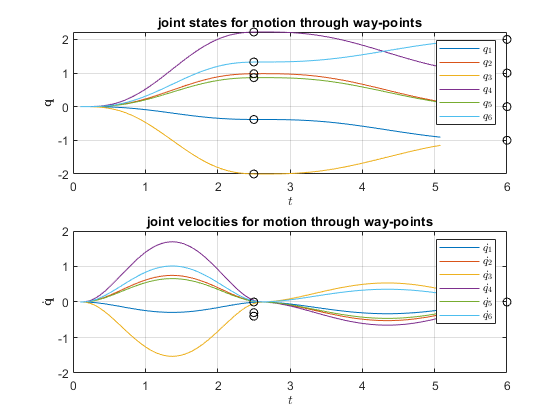

figure(4);
subplot(211);

plot(timeStamp,jointStateStamped);

hold on;
for i=1:size(q_targets,2)
    plot(t_targets(i),q_targets(:,i),'ko')
end
hold off;

xlabel('$t$','Interpreter','Latex');
ylabel('$\mathbf{q}$','Interpreter','Latex');
legend({'$q_1$','$q_2$','$q_3$','$q_4$','$q_5$','$q_6$'},'Interpreter','Latex');
title('joint states for motion through way-points');
grid on

subplot(212);

plot(timeStamp,jointVelStamped);

hold on;
for i=1:size(q_targets,2)
     plot(t_targets(i),qvel(:,i),'ko')
end
hold off;

xlabel('$t$','Interpreter','Latex');
ylabel('$\dot{\mathbf{q}}$','Interpreter','Latex');
legend({'$\dot{q_1}$','$\dot{q_2}$','$\dot{q_3}$','$\dot{q_4}$','$\dot{q_5}$','$\dot{q_6}$'},'Interpreter','Latex');
title('joint velocities for motion through way-points');
grid on